# **CS/SE 4X03 Tutorial Week 8 - Finding Roots**

## **Exercise 1 - 3.1.8**

**Q: **If $a=0.1$ and $b=1.0$, how many steps of the bisection method are needed to determine the root with an error, $\varepsilon$, of at most $\frac{1}{2}\times10^{-8}$?

### Bisection Method Theorem

If the bisection algorithm is applied to a continuous function $f$ on an interval $[a,b]$, where $f(a)f(b)<0$, then after $n$ steps, an approximate root will have been computed with error at most $\frac{(b-a)}{2^{n+1}$.

**Note:** For $f(a)f(b)<0$ we need one end of our function to be above zero, and one below zero, i.e. a root must exist on our interval.

**A: **We will use the bisection method theorem above to calculate the minimum number of iterations required.


$$\frac{b-a}{2^{n+1}} < \varepsilon$$



$$\Rightarrow (b-a) < 2^{n+1}\varepsilon$$



$$\Rightarrow \log(b-a) < \log(2^{n+1}\varepsilon)$$



$$\Rightarrow \log(b-a) < \log(2^{n+1})+\log(\varepsilon)$$


Since, $\log(a\times b) = \log(a)+\log(b)$.


$$\Rightarrow \log(b-a) -\log(\varepsilon)< \log(2^{n+1})$$



$$\Rightarrow \log(b-a)-\log(\varepsilon) < (n+1)\log(2)$$


Since, $\log(x^a)=a\log(x)$.


$$\Rightarrow \log(b-a)-\log(\varepsilon) < n\log(2) + \log(2)$$



$$\Rightarrow \log(b-a) - \log(\varepsilon) -\log(2) < n\log(2)$$



$$\Rightarrow n > \frac{\log(b-a)-\log(2\varepsilon)}{\log(2)$$


Since, $\log(a)+\log(b) = \log(a\times b)$.

With this expression, and our given error tolerance, we can compute the number of iterations required:


$$n > \frac{\log(1.0-0.1)-\log(2\times\frac{1}{2}\times10^{-8})}{\log(2)}$$



$$n > \frac{\log(0.9)-\log(10^{-8})}{\log(2)} = 26.42$$


$\therefore 27$steps are required.

## **Excercise 2 - 3.2.3**

**Q: **Write Newton's method in simplified form for determining the reciprocal of the square root of a positive number. Perform two iterations to approximate $\frac{1}{\pm\sqrt{5}}$, starting with $x_0 =1$ and $x_0 = -1$.

**A: **

**Note: **Reciprical square root of $R$ satisfies: $x^{-2} = R$ or in other words:


$$\Rightarrow x = \frac{1}{\sqrt{R}}, \quad \{R \in\mathbb{R} | R\neq0\}$$


So we want to find the root to the equation:


$$f(x) = x^2 - \frac{1}{R} = 0,\quad $$


and $f'(x) = 2x$

Now using Newton's method:


$$x_{n+1}=x_n-\frac{f(x_n)}{f'(x_n)}$$



$$\Rightarrow x_{n+1} = x_n - \frac{x_n^2-R^{-1}}{2x_n}= x_n - \frac{x_n}{2} +\frac{1}{Rx_n}$$



$$\therefore x_{n+1} = \frac{1}{2}\left[x_n + \frac{1}{Rx_n} \right]$$


Now that we have an equation, we can substitute our value of R to get our answer:

**If** $R=5$ and $x_0=1$, **then** $x_1 = 0.6,\;x_2=0.4667,\;x_3=0.4476...$

**If** $R=5$ and $x_0=-1$, **then** $x_1 = -0.6,\;x_2=-0.4667,\;x_3=-0.4476...$

clear;

R = 5;
x0 = 1;
%x0 = -1;

% Simple implementation of our function
newtonRecip = @(x,R)(1/2*(x+1/(R*x)));

% Loop over our iterates, using the previous x each time
x = x0;
for i = 1:6
    x = newtonRecip(x,R);
    fprintf('x_%d = %.15e  error = %.2e\n',i,x, abs(x- 1/sqrt(R)));
end

x_1 = 6.000000000000000e-01  error = 1.53e-01
x_2 = 4.666666666666667e-01  error = 1.95e-02
x_3 = 4.476190476190476e-01  error = 4.05e-04
x_4 = 4.472137791286727e-01  error = 1.84e-07
x_5 = 4.472135954999956e-01  error = 3.77e-14
x_6 = 4.472135954999579e-01  error = 0.00e+00


## **Exercise 3 - 3.2.14**

**Q: **Determing the formulae for Newton's method for finding a root of the function $f(x)=x-\frac{e}{x}$. What is the behaviour of the iterates?

**A: **Our function is $f(x)=x-ex^{-1}$, this means that our derivative is $f'(x) = 1+ex^{-2}$.

If we use Newton's method we have:


$$x_{n+1}=x_n-\frac{f(x_n)}{f'(x_n)}$$



$$x_{n+1} = x_n - \frac{x_n-ex^{-1}}{1+ex^{-2}}$$


Now we multiply by the fraction by: $\frac{x_n^2}{x_n^2}$ to remove the fraction in denominator


$$=x_n - \frac{x_n^3-ex_n^}{x_n^2+e}$$
 

Let's group everything under a common denominator, and then simplify:


$$=\frac{x_n^3 + ex_n - x_n^3+ex_n^}{x_n^2+e}$$



$$= \frac{2ex_n}{x_n^2+e}$$


Since $x-\frac{e}{x}=0$ we can this will converge to $\sqrt{e}$.


$$\frac{2e\sqrt{e}}{e+e}=\sqrt{e}$$


% very simply, we can use this equation to iterate
% we can use this as a simple check for our iterate behaviour
e = exp(1);
f = @(x) x - e./x ; %x.^2 - e;
df = @(x) 1 + e./x.^2 ;%2*x;
clf
fplot(f, [-3 3]); hold on; fplot(0, [-3, 3])
x = 1;
for i = 1:5
    x = x - f(x)/df(x); 
    fprintf('x_%d = %.15e  error = %.2e\n',i,x, abs(x^2- e));
end

x_1 = 1.462117157260010e+00  error = 5.80e-01
x_2 = 1.636898891894865e+00  error = 3.88e-02
x_3 = 1.648678578685937e+00  error = 1.41e-04
x_4 = 1.648721270147380e+00  error = 1.82e-09
x_5 = 1.648721270700128e+00  error = 0.00e+00


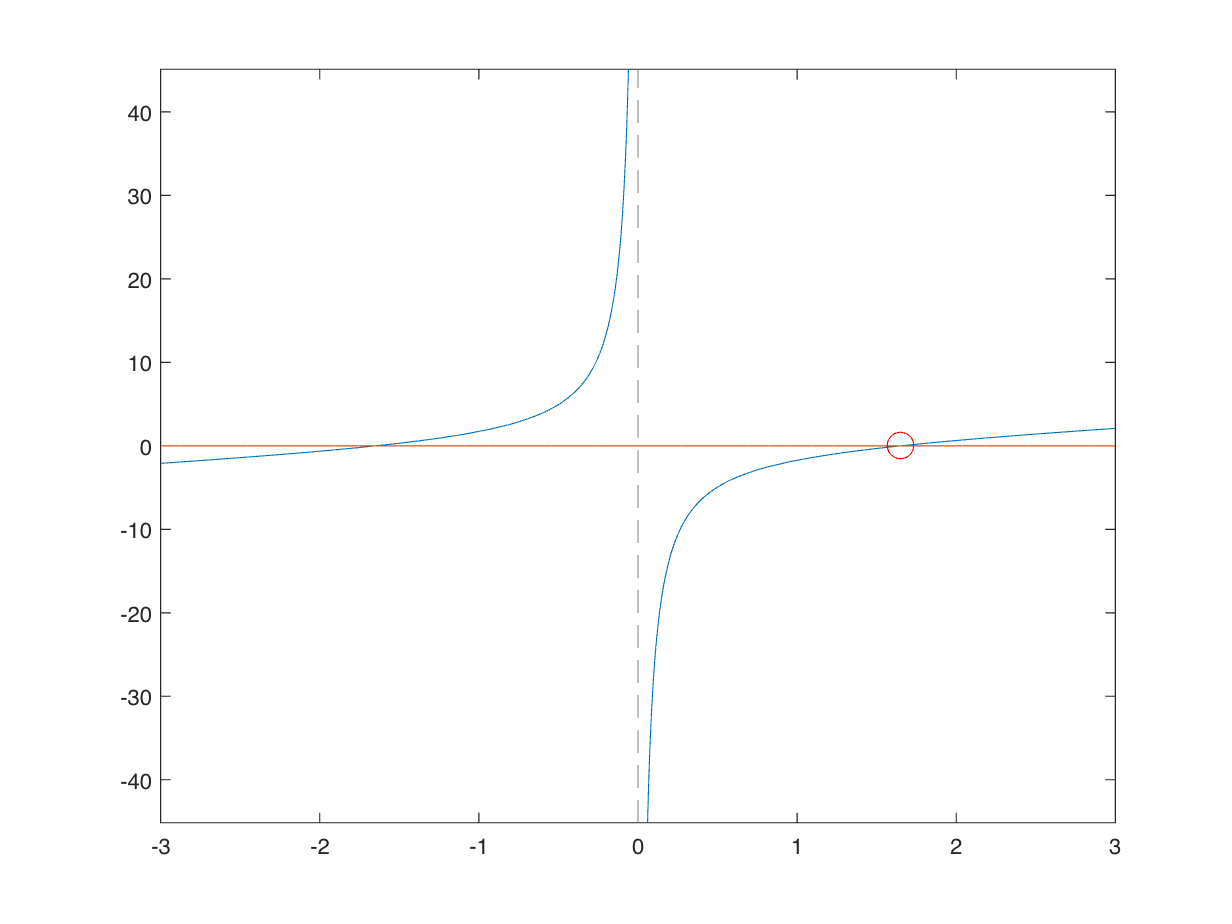

plot(x, f(x), 'ro', 'MarkerSize', 12)

## **Exercise 4 - 3.3.2**

**Q: **If we use the secant method on $f(x) = x^3 -2x+2%$, starting with $x_0=0$ and $x_1=1$, what is $x_2$?

**A:**

**Recall - Secant Method:**


$$x_{n+1}=x_n-\left(\frac{x_n-x_{n-1}}{f(x_n)-f(x_{n-1})}\right)f(x_n)$$


For $n \geq 1$, which requires two initial values $x_0$ and $x_1$, after the first step only one new function evaluation per step is needed.

Given, $f(x) = x^3 - 2x + 2$


$$x_0 = 0 \Rightarrow f(x_0) = f(0) = 2$$



$$x_1 = 1 \Rightarrow f(x_1) = f(1)=1$$



$$x_2 = x_1 - \left(\frac{x_1 - x_0}{f(x_1) - f(x_0)}\right)f(x_1)$$



$$x_2 = 1-\left(\frac{1-0}{1-2}\right) = 2$$


## **Exercise 5 - 3.3.3**

**Q: **If we use the secant method on $f(x) = x^5+x^3+3$ starting with $x_{n-2}=0$ and $x_{n-1}=1$, what is the $x_n$?

**A:**

Given, $f(x) = x^5 +x^3+3$


$$x_{n-2} = 0 \Rightarrow f(x_{n-2}) = f(0) = 2$$



$$x_{n-1} = 1 \Rightarrow f(x_{n-1}) = f(1)=5$$



$$x_n = x_{n-1} - \left(\frac{x_{n-1} - x_{n-2}}{f(x_{n-1}) - f(x_{n-2})}\right)f(x_{n-1})$$



$$x_2 = 1-\left(\frac{1-0}{5-2}\right)\times5 =- \frac{2}{3}$$


## Basins of Attraction With Newton's Method

Newton's Method, when applied to a function $f(z)$, where $z \in\mathbb{C}$, gives us distinct regions corresponding to what value an initial condition converges to after many iterations.

Let's first consider the real valued function $f(x)=x^2-1$.

If we want to find the roots of this equation we want to solve: $f(x)=0=x^2-1$ we know can employ Newton's method:


$$f(x)=x^2-1$$



$$f'(x)=2x$$



$$x_{n+1}=x_n-\frac{f(x_n)}{f'(x_x)}=x_n-\frac{x_n^2-1}{2x}$$


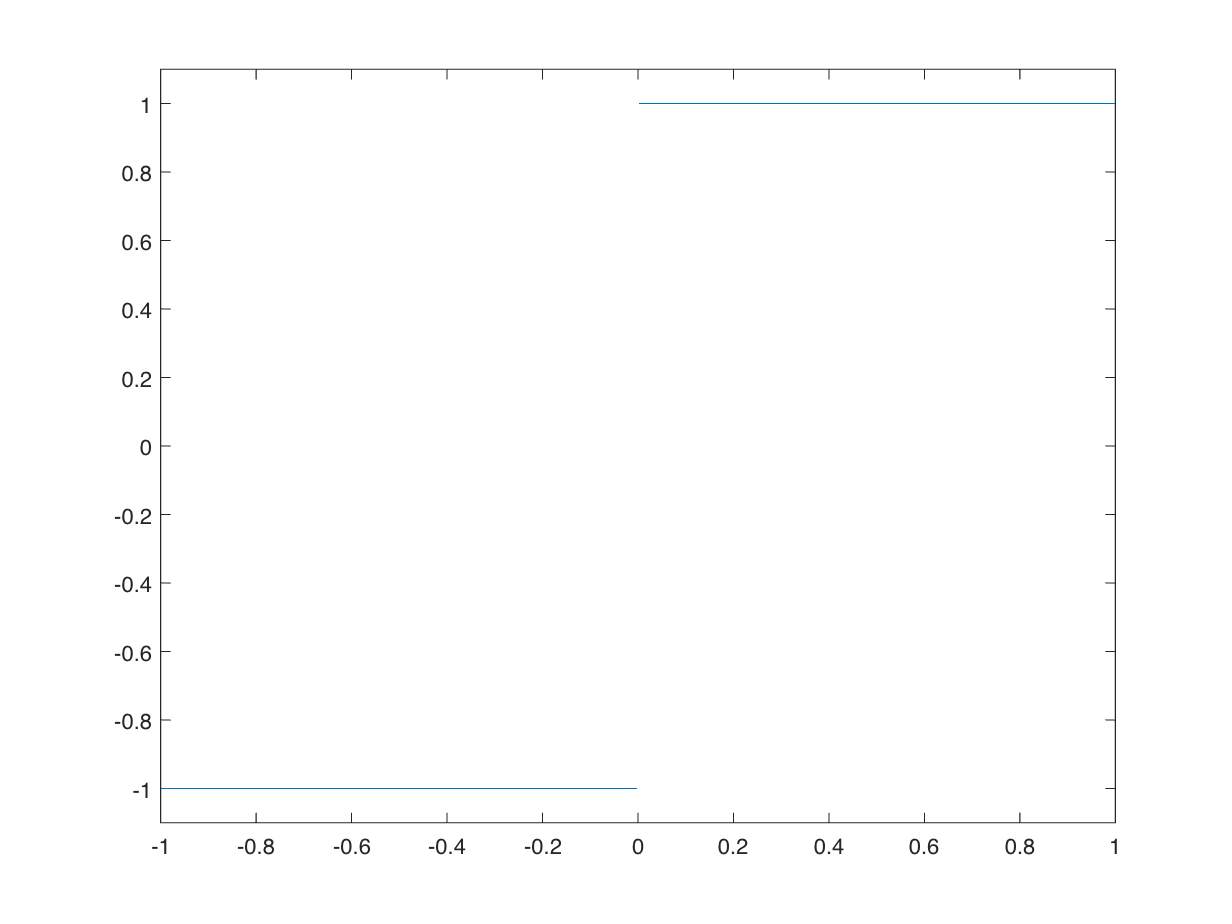

clear; clf

t = -1:0.002:1;
x = t;
f = @(x)(x.^2-1);
df = @(x)(2*x);

maxIt = 20;

for i = 1:maxIt
    x=x-f(x)./df(x);
end

plot(t,x);
ylim([-1.1 1.1]);

We can see here that this plot converges into two distinct roots. 

If $x_0 < 0$, $x_k=-1$. Similarly,  if $x_0 > 0, x_k = 1$. Where $k$ is the maximum number of iterations.

If we consider the function analytically, this is precisely what we should expect.


$$f(x)=0=x^2-1$$



$$\Rightarrow x^2=1$$


Which obviously has roots $r_1 = -1, r_2 = 1$.

**Note:** If we consider only a couple of iterations, and near $x_0=0$ we can observe some strange behaviour.

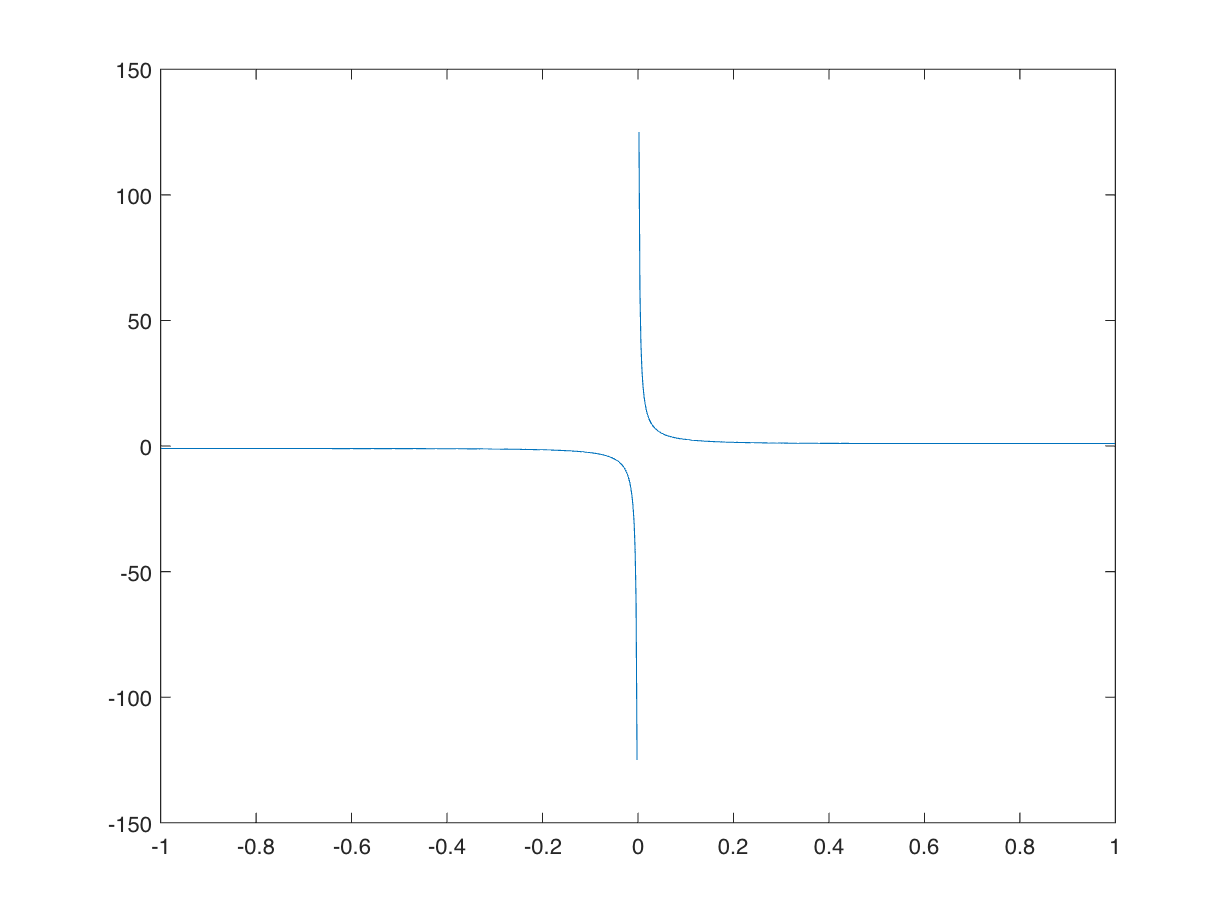

maxIt = 2;
x= t;
for i = 1:maxIt
    x=x-f(x)./df(x);
end

plot(t,x);

This ultimately is not too surprising, as we are approaching a discontinuity in our Newton equation.

### The Complex Plane

Let us now consider the complex case. Assume that we have some $z=x+iy$, where $\sqrt{i}=-1$. We can define some $f:\mathbb{C}\rightarrow\mathbb{C}$, that is equivalent to the real valued case we considered before:


$$f(z)=z^2-1$$



$$\Rightarrow f'(z)=2z$$


Here, there are two solutions to this equation $r_f=\pm1$. We can attempt this, and colour based upon which root our function falls into. If our function converges to -1 we will colour it green, if it converges to +1 we will colour it blue. We will colour values that do not converge yellow. 

This colouring will refer to our **basins of attraction**. Any point coloured the same will converge to the same value, given enough iterations.

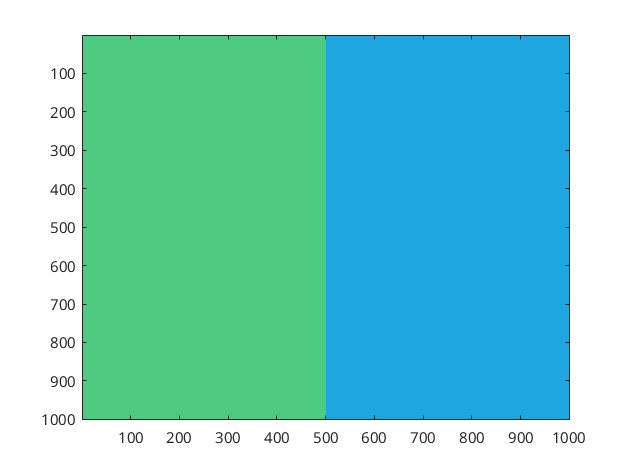

clear;
clf;

% Spatial array (storing positions)
x = -1:0.002:1; y = -1:0.002:1;
[x0, y0] = meshgrid(x,y);
% Image array (storing colours)
n = zeros(size(x0));
tol = 1e-6;
maxIt = 30;

% Our complex function and derivative
%   Needed for Newton-Raphson
f = @(z)(z.^2-1);
df = @(z)(2*z);

% z := x + iy
z = x0 + 1i*y0;

% Found using DeMoivre's Theorem
root1 = -1;
root2 = 1;

% Iterate using Newton-Raphson method
for itr = 1:maxIt
    z = z-f(z)./df(z);
end

% We will loop over the y,x to get each point
for k = 1:length(y)
    for m = 1:length(x)
        if abs(z(k,m) - root1) < tol
          n(k,m) = 156;
        elseif abs(z(k,m)-root2) < tol
          n(k,m) = 100;
        else
          n(k,m) = 256;
        end
    end
end
image(n);

And we can see behaviour we might expect, if $\Re(z) < 0$, our function converges to -1. If $\Re(z)>0$ our function converges to +1.

**Aside: **If we consider the function $f(z)=z^2+1$, we can see that our roots will be $r_f=\pm i$. This results in our image essentially being rotated.

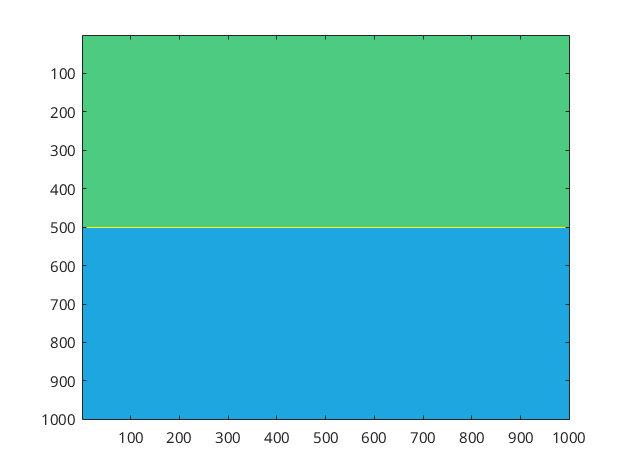

f = @(z)(z.^2+1);
df = @(z)(2*z);

% z := x + iy
z = x0 + 1i*y0;

% Found using DeMoivre's Theorem
root1 = -i;
root2 = i;

% Iterate using Newton-Raphson method
for itr = 1:maxIt
    z = z-f(z)./df(z);
end

% We will loop over the y,x to get each point
for k = 1:length(y)
    for m = 1:length(x)
        if abs(z(k,m) - root1) < tol
          n(k,m) = 156;
        elseif abs(z(k,m)-root2) < tol
          n(k,m) = 100;
        else
          n(k,m) = 256;
        end
    end
end
image(n);

### But Complex Numbers are... Complex

Let us look at the function:

 
$$f(z)=z^3-1,z\in\mathbb{C}$$


Unlike the real valued equivalent, which only has a root at $x=1$, because our function is complex, we have three roots. (*Details on this at the bottom of this script if you are unsure why there are three*)


$$r_1 = 1$$



$$r_2 = -\frac{1}{2} + \frac{\sqrt{3}}{2}i$$



$$r_3 = -\frac{1}{2} - \frac{\sqrt{3}}{2}i$$


**BEFORE CONTINUING:** Consider what you suspect the plot will look like. Last time we had basins of attraction that resulted in essentially the chopping up of our space, based upon the convergence behaviour of our function in that space. It would be reasonable to assume that given we have three roots, that we might expect the region to be split up into thirds meeting at the center (where $\Re(z) \approx \Im(z) \approx 0$).

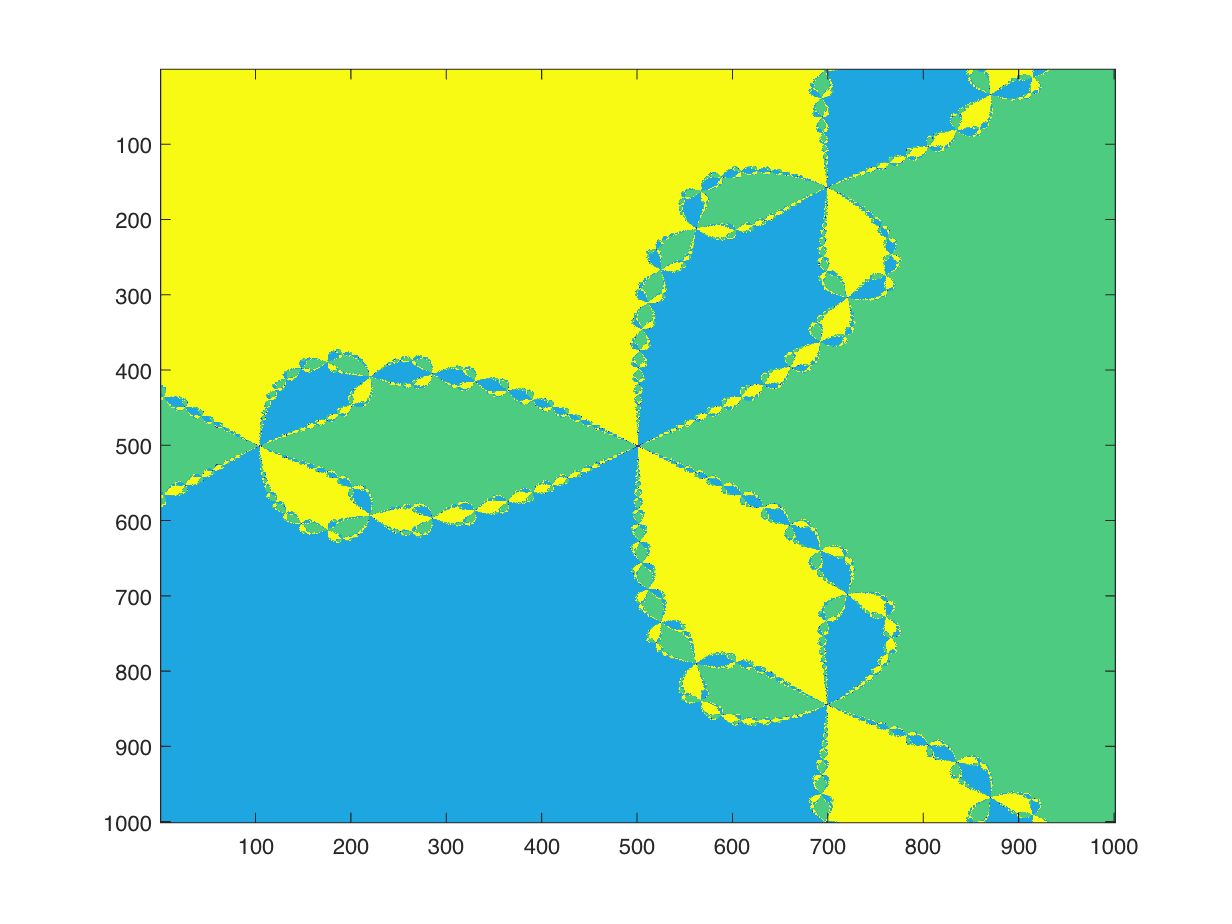

clear;
clf;

% Spatial array (storing positions)
x = -1:0.002:1; y = -1:0.002:1;
[x0, y0] = meshgrid(x,y);
% Image array (storing colours)
n = zeros(size(x0));
tol = 1e-6;
maxIt = 30;

% Our complex function and derivative
%   Needed for Newton-Raphson
f = @(z)(z.^3-1);
df = @(z)(3*z.^2);

% z := x + iy
z = x0 + i*y0;

% Found using DeMoivre's Theorem
root1 = 1;
root2 = -1/2+sqrt(3)/2*1i;
root3 = -1/2-sqrt(3)/2*1i;

% Iterate using Newton-Raphson method
for itr = 1:maxIt
    z = z-f(z)./df(z);
end

% We will loop over Im(z), Re(z) to get each point
for k = 1:length(y)
    for m = 1:length(x)
        if abs(z(k,m) - root1) < tol
          n(k,m) = 156;
        elseif abs(z(k,m)-root2) < tol
          n(k,m) = 100;
        elseif abs(z(k,m)-root3) < tol
          n(k,m) = 256;
        else
            n(k,m) = 0;
        end
    end
end
image(n);

Pretty neat!

Sincee our function is in the complex plane, which means we can express our number as $re^{i\theta}$, out iterations actually occur in $\theta$! This results in our iterations moving from basins of similar colour as they spiral towards the actual root. 

**Bonus:** I didn't have time, but proving this to yourself, either mathematically, or graphically (plotting the iterations of a point in the space) is a good way to introduce yourself to fractal math!

This plot has some very fascinating properties:

- It is self-similar. As we zoom in, or move around the image, we will see the same patterns repeated.

- Detailed structure at arbitrary scales. No matter how far we zoom in, we will still see detail.

So if we zoom in on or move around our image we still have the roughly the same picture!

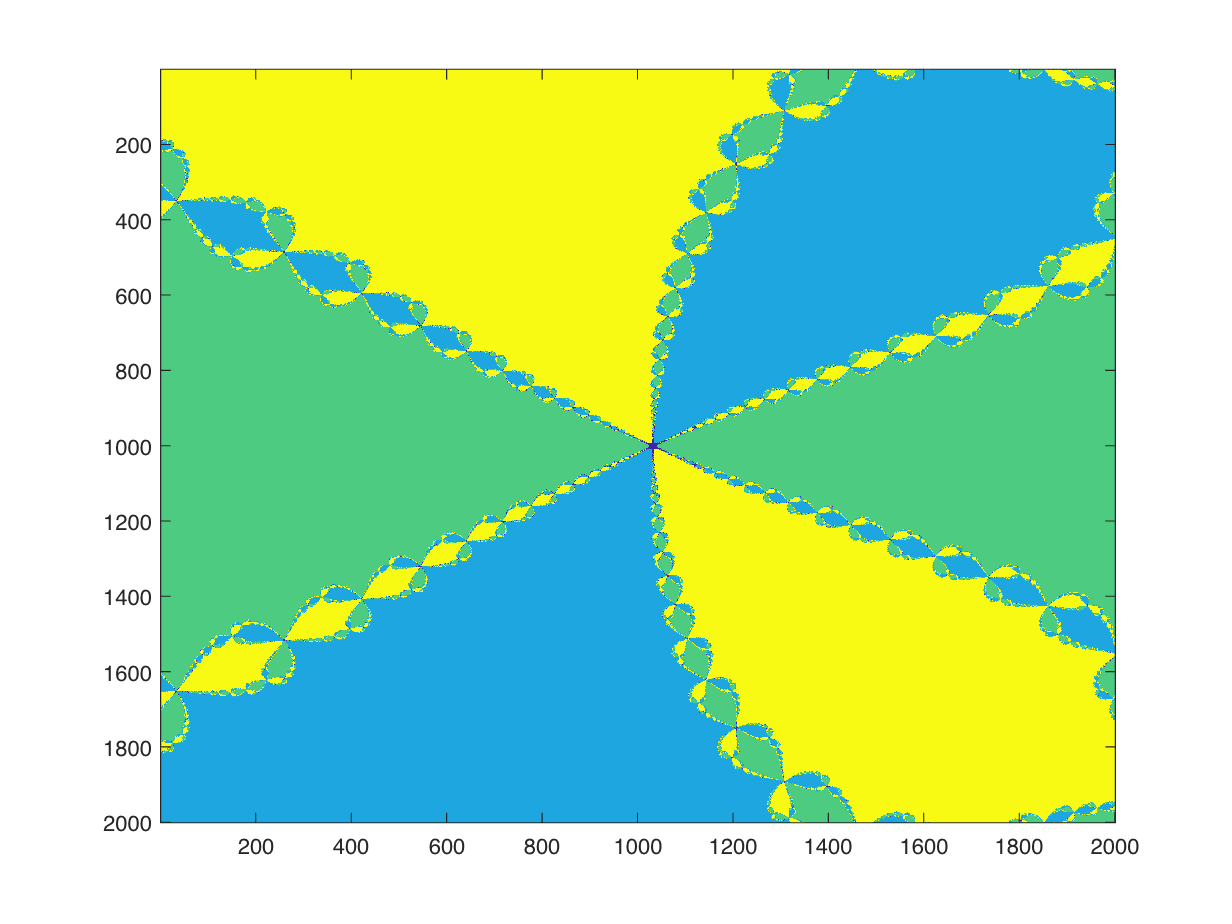

% This time we will move over and zoom in
clear;
clf;

% Spatial array (storing positions)
x = -1:0.0002:-0.6; y = -0.2:0.0002:0.20;
[x0, y0] = meshgrid(x,y);
% Image array (storing colours)
n = zeros(size(x0));
tol = 1e-6;
maxIt = 30;

% Our complex function and derivative
%   Needed for Newton-Raphson
f = @(z)(z.^3-1);
df = @(z)(3*z.^2);

% z := x + iy
z = x0 + 1i*y0;

% Found using DeMoivre's Theorem
root1 = 1;
root2 = -1/2+sqrt(3)/2*1i;
root3 = -1/2-sqrt(3)/2*1i;

% Iterate using Newton-Raphson method
for itr = 1:maxIt
    z = z-f(z)./df(z);
end

% We will loop over Im(z), Re(z) to get each point
for k = 1:length(z)
    for m = 1:length(z)
        if abs(z(k,m) - root1) < tol
          n(k,m) = 156;
        elseif abs(z(k,m)-root2) < tol
          n(k,m) = 100;
        elseif abs(z(k,m)-root3) < tol
          n(k,m) = 256;
        else
            n(k,m) = 0;
        end
    end
end
image(n);

**Very **similar to what we just had!

If we choose one root, we can instead colour our image based on the number of iterations it takes to converge to the root.

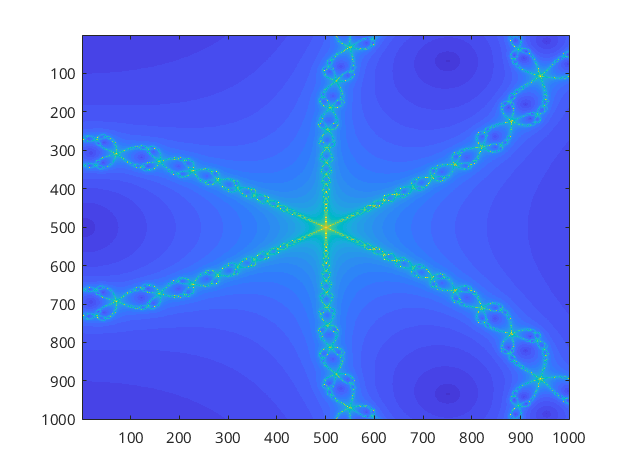

clear;
clf;

x = -0.5:0.001:0.5; y = -0.5:0.001:0.5;
[x0, y0] = meshgrid(x,y);
n = zeros(size(x0));
tol = 1e-6;
maxIt = 100;

f = @(z)(z.^3-1);
df = @(z)(3*z.^2);

% Loop over the pixels
for k = 1:length(y)
  for m = 1:length(x)
    % Compute each pixel indepedently
    z = x0(k,m) + i*y0(k,m);
    % Iterated until tolerance,
    for itr = 1:maxIt
      z = z - f(z)./df(z);
      % This cubing gives *beautiful* results
      if abs(z.^3 - 1) < tol
        n(k,m) = itr; break,
      end
    end
  end
end
imagesc(n,[1 40]);

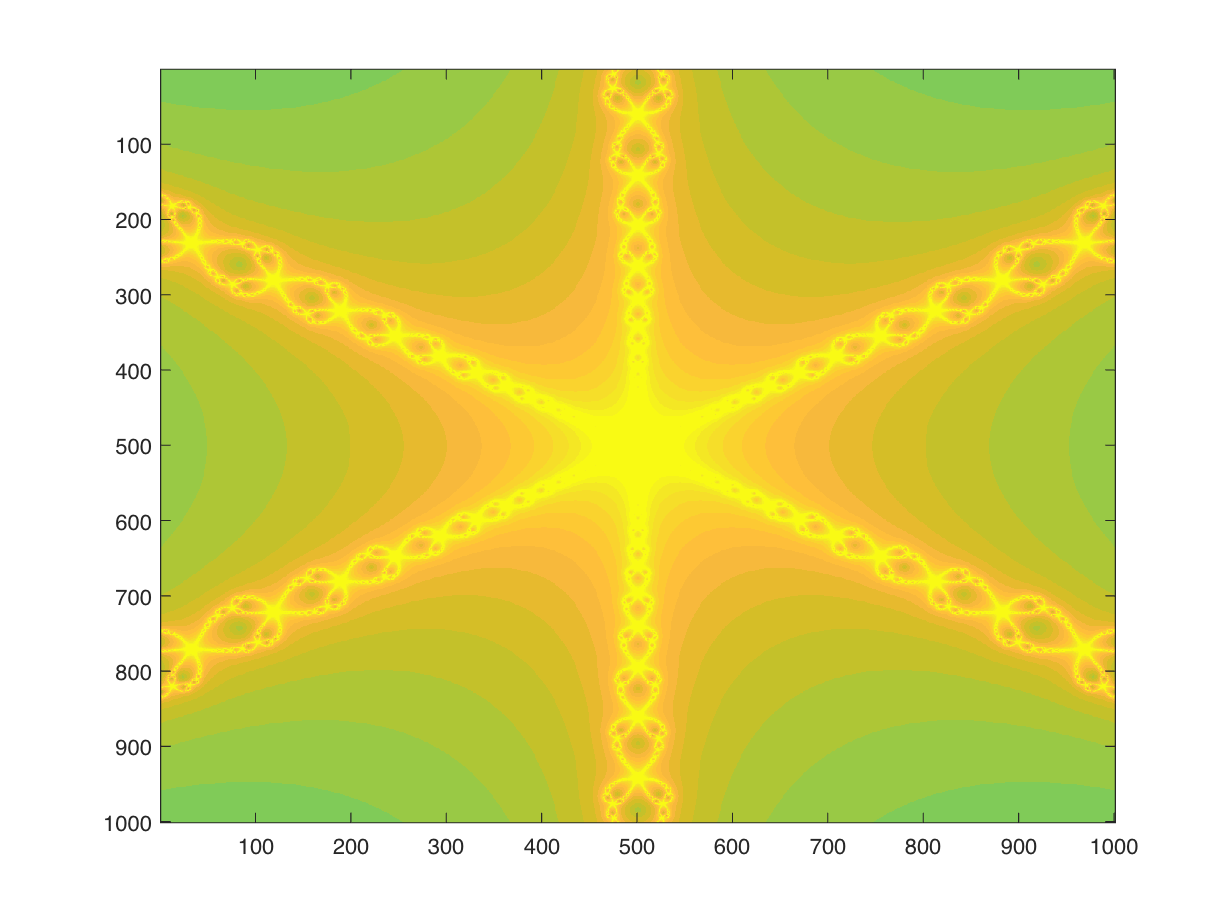

% Just zooming in
clear;
clf;

x = -0.005:0.00001:0.005; y = -0.005:0.00001:0.005;
[x0, y0] = meshgrid(x,y);
n = zeros(size(x0));
tol = 1e-6;
maxIt = 100;

f = @(z)(z.^3-1);
df = @(z)(3*z.^2);

% Loop over the pixels
for k = 1:length(y)
  for m = 1:length(x)
    % Compute each pixel indepedently
    z = x0(k,m) + i*y0(k,m);
    % Iterated until tolerance,
    for itr = 1:maxIt
      z = z - f(z)./df(z);
      % This cubing gives *beautiful* results
      if abs(z.^3 - 1) < tol
        n(k,m) = itr; break,
      end
    end
  end
end
imagesc(n,[1 40]);

% DeMoivre's Theorem is how you should find these roots...
% ...but if you are bad at math symbolic tools exist
clear;
syms z;
f = z^3 - 1;
root = solve(f)

$$root = \left(\begin{array}{c} 1\\ -\frac{1}{2}-\frac{\sqrt{3}\,\mathrm{i}}{2}\\ -\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2} \end{array}\right)$$

#### Some Extra Math

Using a polar plot, we can write out any complex number as:


$$z=a + b\text{i} = \sqrt{a^2+b^2}(\cos\theta+\text{i}\sin\theta)$$


Where,


$$\theta = \text{atan2}(b,a)$$


We can rewrite this using Euler's Formula as:


$$z=re^{\text{i}\theta},\quad r=\sqrt{a^2+b^2}$$


Now consider we are trying to solve the problem: $z^n=1$ or alternatively,


$$z = \sqrt[n]{1}$$


But we know (from above) we can express this alternatively as:


$$z = \sqrt[n]{\cos\theta+\text{i}\sin\theta}$$


Now we use **De Moivre's Theorem**:


$$(\cos x + \text{i}\sin x)^n = \cos(nx) + \text{i}\sin(nx)$$



$$z = \cos \left(\frac{\theta}{n}\right) + \text{i}\sin\left(\frac{\theta}{n}\right)$$


And we can see this has $n$ roots for, $\theta_k=\theta+2\pi k$ where $k=1,...,n$


$$z=0 \Rightarrow r_k = \cos \left(\frac{2\pi k}{n}\right) + \text{i}\sin \left(\frac{2\pi k}{n}\right)$$


for k = 1:3
    cos(2*pi*k/3)+i*sin(2*pi*k/3)
end

ans = -0.5000 + 0.8660i

ans = -0.5000 - 0.8660i

ans = 1.0000 - 0.0000i